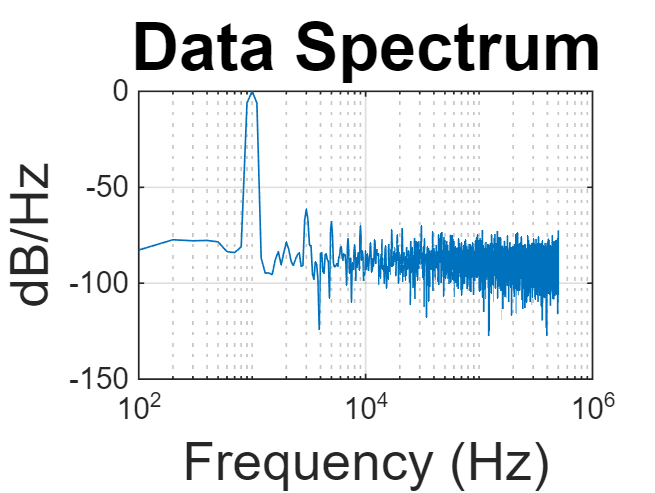

@Freq = 1000.000, SNR = 50.680 dB, SNDR = 50.228 dB, SFDR = 61.450 dB, HD2 = 78.362 and HD3 = 61.450


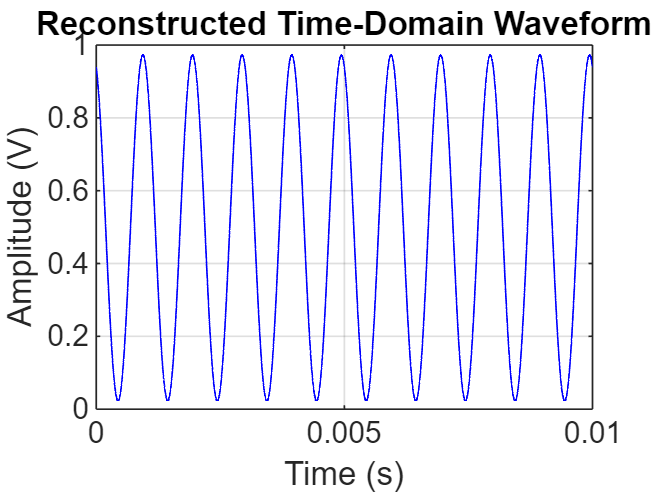

clearvars
freq_array = readtable('./ADC_Data/Board2/11-25-Python-Sweep-1MHz-50%-1020mV/freq_array.csv');
freq_array = table2array(freq_array);
freq_array = floor(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/Board2/11-25-Python-Sweep-1MHz-50%-1020mV/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'Hz_1020mV---CLK_1MHz_50%.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);
    data_Code_dec = bin2dec(num2str(data_Code));

    rising_edge_indices = find(diff(data_EOC) == -1);
    time_diff = diff(rising_edge_indices);
    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code_dec(index);

    end
    data_NewDec = data_NewCode;
    % data_NewDec = floor(medfilt1(data_NewCode, 3));
    % data_NewDec = data_NewDec(1:5000);
    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =Fs/2;
    sample_size=length(data_NewDec);
    % sample_size=length(data_NewDec);
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

save('./ADC_Data/Board2/11-25-Python-Sweep-1MHz-50%-1020mV/BigSet.mat', 'BigSet');

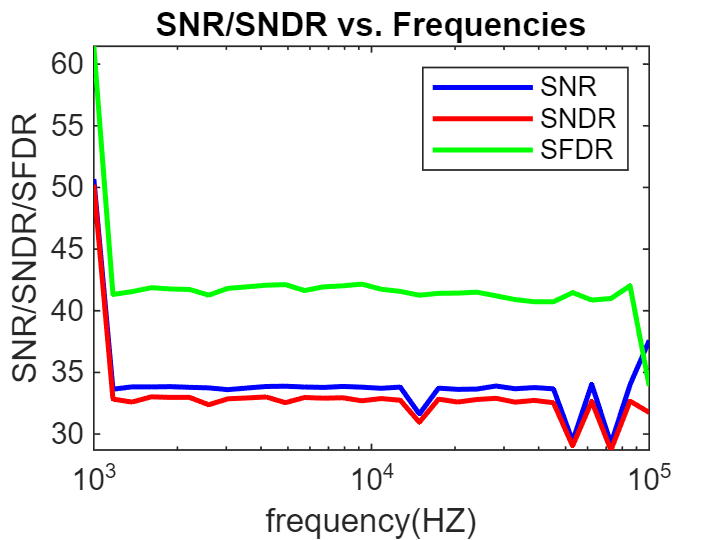

save('BigSet.mat', 'BigSet');
load('./ADC_Data/Board2/11-25-Python-Sweep-1MHz-50%-1020mV/BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;

% Detect crossings: Where signal crosses 0.5
threshold = 512/2;
crossing_indices = find((data_NewDec(1:end-1) < threshold & data_NewDec(2:end) >= threshold) | ...
                        (data_NewDec(1:end-1) >= threshold & data_NewDec(2:end) < threshold));

% Count crossings
num_crossings = length(crossing_indices);

% Display result
fprintf('Number of crossings: %d\n', num_crossings);

Number of crossings: 46


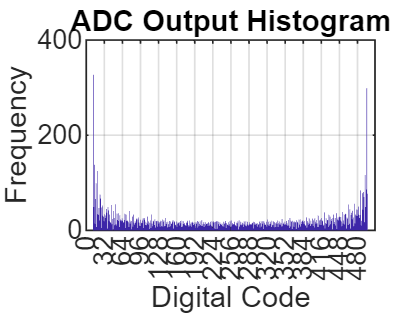

% Define bin edges for an 8-bit ADC (0-255)
bin_edges = 0:2^9-1;

% Calculate the histogram
[hits, codes] = histcounts(data_NewDec, bin_edges);
figure;
bar(codes(1:end-1), hits, 'histc');  % Use 'histc' to align bars
grid on;
title('ADC Output Histogram');
xlabel('Digital Code');
ylabel('Frequency');
xlim([0 511]);  % Adjust to match ADC range
xticks(0:32:511);  % Optional: Tick marks for better visualization

ADC_bits = 9;
VFS = 1;
Amp = VFS/2;
total_sampels = length(data_NewDec);

% codes = codes(20:end-20);
% hits = hits(20:end-20);
DNL = zeros(length(codes),1);
p =zeros(length(codes),1);
hits_prob = zeros(length(codes),1);
hits_sum = sum(hits);
ideal_hits = hits_sum/(2^ADC_bits-1)

ideal_hits = 19.5695

for i = 1:length(hits)
    p = calc_Prob(VFS, codes(1,i), ADC_bits, Amp) ; 
    DNL(i) = ( hits(1,i) / (hits_sum)*p); 
    % DNL(i) = ( hits(1,i)-ideal_hits / (ideal_hits))/hits_sum -1/hits_sum;
    DNL(i) = ( hits(1,i)-ideal_hits / (ideal_hits));
    % display(p);
    % display(DNL(i));
    % display(p);
    % display(p_n_norm);
end
DNL_sum = sum(DNL)

DNL_sum = 9489

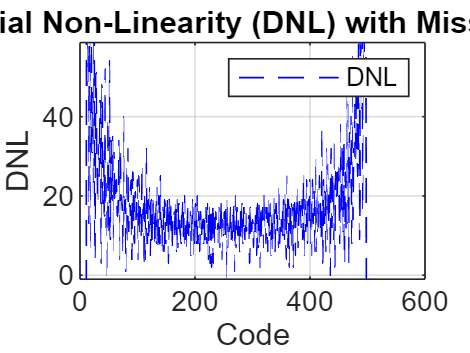

figure
plot(codes,DNL,'b--',"DisplayName","DNL")
xlabel("Code")
ylabel("DNL")
ylim([-1,ideal_hits*3])
% xlim([0 7e4])
% ylim-()
title("Differential Non-Linearity (DNL) with Missing Codes")
legend;
grid on

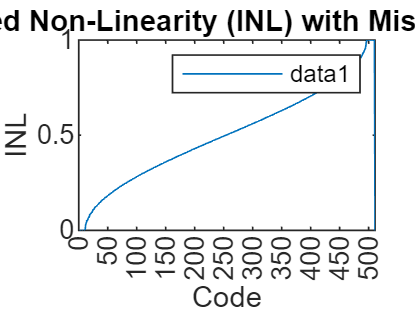

INL = zeros(length(codes),1);


for i = 1:length(hits)
    INL(i) = sum(DNL(1:i,1));
end

figure
plot(codes(1,:),INL(:,1))
xlabel("Code")
ylabel("INL")
title("Integrated Non-Linearity (INL) with Missing Codes")
legend;
xlim([0 511]);  % Adjust to match ADC range
xticks(0:50:511);

function p = calc_Prob(VFS, n, bits, amp)
     % VFS: Full scale of ADC input
     % n: is the code
     % bits: number of bits of the ADC
     % amp: amplitude
     asin_part1 = asin((VFS*(n - 2^(bits-1))) / (amp * 2^bits));
     asin_part2 = asin((VFS*(n-1-2^(bits-1))) / (amp * 2^bits));
     % asin_part1 = min(max(asin_part1, -1), 1);
     % asin_part2 = min(max(asin_part2, -1), 1);
     p = 1/pi * (asin_part1 - asin_part2);
end